# Angle of attack (AOA) response 

omega=56;
I=0.002178279;
% I = 0.00864
Matrix = zeros(1,100)

Matrix =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k= 2.5

k = 2.5000


nat_freq= sqrt(k/I)

nat_freq = 33.8776

theta_req = 5.1.*pi/180

theta_req = 0.0890

theta_default = 5.*pi/180;      % Offset of graph (oscillates around theta default rather than 0)
t= pi/(2.*omega)

t = 0.0280

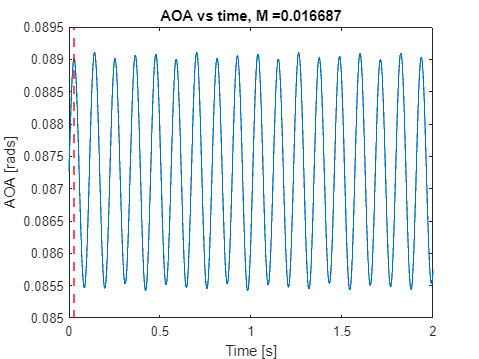


% M = (theta_req - theta_default.*cos(nat_freq.*t))/(1/(omega.^2.*I+k)-sin(nat_freq.*t)./((omega.^2.*I+k).*(nat_freq))) 
M = (theta_req-theta_default)/(1/(omega.^2.*I+k)-sin(nat_freq.*t)./((omega.^2.*I+k).*(nat_freq))); 
% theta = @(x) -M/((omega.^2.*I+k).*(nat_freq)).*sin(nat_freq.*x) +theta_default.*cos(nat_freq.*x) + M/(omega.^2.*I+k).*sin(omega.*x)
theta = @(x) -M/((omega.^2.*I+k).*(nat_freq)).*sin(nat_freq.*x) + M/(omega.^2.*I+k).*sin(omega.*x) + theta_default;

x=0:0.001:2;
y=theta(x);
plot(x,y)
xlabel('Time [s]');
ylabel('AOA [rads]');
title(['AOA vs time, M =', num2str(M)]);
xline(2.*pi/omega/4, '--r', 'LineWidth', 1.5);

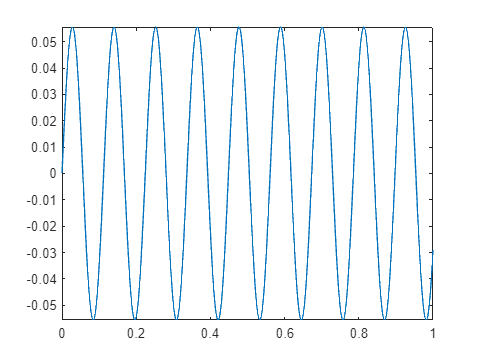


fplot(@(x) M.*sin(x.*omega)/0.3,[0:1])

M

M = 0.0167

k= 1

k = 1

theta_req = 8.*pi/180

theta_req = 0.1396

theta_default = 5.*pi/180; 
theta_prev = 0;
M = k.*(theta_req - (theta_prev).*cos(nat_freq.*t))./(1-cos(nat_freq.*t))

M = 0.3336

theta2= @(x) (theta_prev-M/k).*cos(nat_freq.*x) + M/k

theta2 = function_handle with value:
    @(x)(theta_prev-M/k).*cos(nat_freq.*x)+M/k


theta2(x)

ans =          0    0.0002    0.0008    0.0017    0.0031    0.0048    0.0069    0.0093    0.0122    0.0154    0.0190    0.0229    0.0272    0.0318    0.0368    0.0422    0.0478    0.0538    0.0601    0.0668    0.0737    0.0809    0.0884    0.0963    0.1043    0.1127    0.1213    0.1301    0.1392    0.1485    0.1580    0.1677    0.1776    0.1876    0.1979    0.2083    0.2188    0.2295    0.2403    0.2512    0.2622    0.2733    0.2844    0.2956    0.3069    0.3182    0.3295    0.3408    0.3521    0.3633


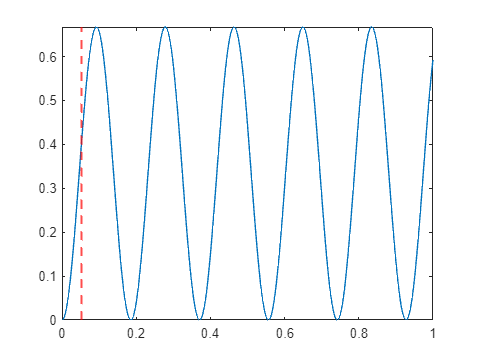


fplot(theta2,0:1)
xline(2.*pi/30/4, '--r', 'LineWidth', 1.5);

### Critically Damped

k=2.4

k = 2.4000

theta_prev = 0;
theta_req = 10.*pi/180

theta_req = 0.1745

theta_default = 0.*pi/180; 
t= pi/(2.*omega)*100

t = 2.8050


% M = k.* (theta_req - theta_prev.*exp(-nat_freq.*t).*(1+nat_freq.*t))./(1+(-1-nat_freq.*t).*exp(-nat_freq.*t)) 
M = k.* theta_req

M = 0.4189

% M=0.04
c=2*sqrt(k.*I)

c = 0.1446

theta_damped = @(x) (theta_prev- M/k).*(1 + nat_freq.*x).*exp(-nat_freq.*x) + M/k

theta_damped = function_handle with value:
    @(x)(theta_prev-M/k).*(1+nat_freq.*x).*exp(-nat_freq.*x)+M/k


theta_damped(t)*180/pi

ans = 10

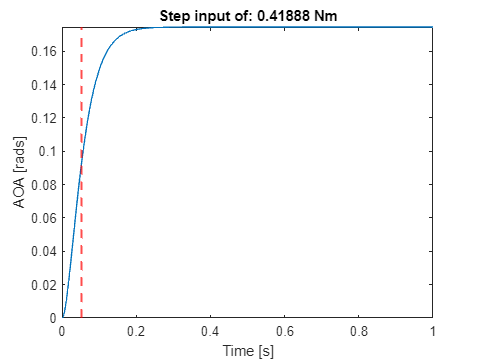

fplot(theta_damped,0:1)
xlabel('Time [s]');
ylabel('AOA [rads]');
title(['Step input of: ', num2str(M),' Nm']);
xline(2.*pi/30/4, '--r', 'LineWidth', 1.5);

### Under Damped

theta_req =5.*pi/180

theta_req = 0.0873

omega =40

omega = 40

k=2.4

k = 2.4000

% c=2*sqrt(k.*I);
C= 0.05

C = 0.0500

theta_prev = 0; %5.*pi/180
T= pi/(2.*omega);
x=0:0.001:0.7;


damping_ratio = C./(2.*sqrt(k.*I))

damping_ratio = 0.3458

wd = nat_freq.*sqrt(1-damping_ratio.^2)

wd = 31.7881

phi = atan(wd./((damping_ratio.*nat_freq)))

phi = 1.2177

M = (theta_req).*k 

M = 0.2094

% M=0.08
A = (theta_prev - M/k)./sin(phi)

A = -0.0930


theta_underdamped = @(x) A.*exp(-damping_ratio.*nat_freq.*x) .* sin(wd.*x + phi) + M/k 

theta_underdamped = function_handle with value:
    @(x)A.*exp(-damping_ratio.*nat_freq.*x).*sin(wd.*x+phi)+M/k


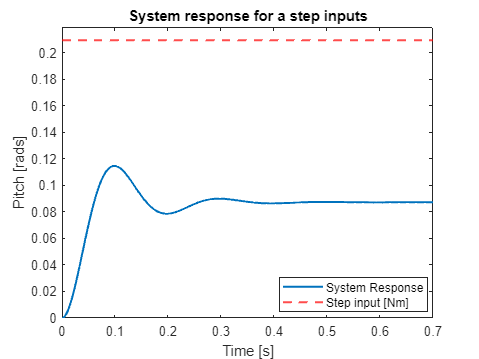


plot(x,theta_underdamped(x),'linewidth',1.5)
yline(M,'--r', 'lineWidth', 1.5)
% xline(pi/(2.*omega), '--r', 'LineWidth', 1.5);
% xline(pi/(2.*omega).*4, '--b', 'LineWidth', 1.5);
ylim([0,M+0.01])
xlabel('Time [s]');
ylabel('Pitch [rads]');

% title(['Step input of: ', num2str(M),' Nm']);
title("System response for a step inputs")
legend(["System Response","Step input [Nm]"])
legend("Position", [0.58316,0.13045,0.31106,0.0961])

M/0.2

ans = 1.0472

spring_mat =zeros(1,681);
damp_mat =zeros(1,681);
spring_damping = zeros(68,68);

### Under Damped sinusoidal input

omega = 30

omega = 30



theta_req = 5.*pi/180

theta_req = 0.0873

damping =0

damping = 0

spring =0

spring = 0

% for damping =  0.1:1:68.1
%     for spring = 0.1:1:68.1
    k= spring/10;
    k=3.6;
    c=2*sqrt(k.*I);
    C= c-0.005;
    % % C=.05
    C= damping/1000;
    C=0.01;
    theta_prev = 0;
        
    T= pi/(2.*omega);
    nat_freq= sqrt(k/I);
    M=1;
    damping_ratio = C./(2.*sqrt(k.*I));
    wd = nat_freq.*sqrt(1-damping_ratio.^2);
    % phi = atan(wd./((damping_ratio.*nat_freq)))
    % M = theta_req.*k
    % A = (theta_prev - M/k)./sin(phi
    for i = 1:2
    X = (M./I)./(sqrt((nat_freq.^2 - omega.^2).^2 + (2 .* damping_ratio .* nat_freq .* omega ).^2));
    beta = atan( (2 .* damping_ratio .* nat_freq .* omega )./(nat_freq.^2 - omega.^2));
    
    phi = atan((wd.*(theta_prev- X.*cos(beta)))./((theta_prev-X.*cos(beta)).*damping_ratio.*nat_freq - omega.*X.*cos(beta)));
    A = (theta_prev -X.*cos(beta))/sin(phi);
    
    
    X_M = (theta_req - ((exp(-damping_ratio.*nat_freq.*T).*(theta_prev.*sin(wd.*T + phi)))./sin(phi)))./(cos(omega.*T - beta) - (exp(-damping_ratio.*nat_freq.*T)).*(cos(beta).*sin(wd.*T + phi))./sin(phi));
    M = (X_M.*I).*(sqrt((nat_freq.^2 - omega.^2).^2 + (2 .* damping_ratio .* nat_freq .* omega ).^2));
    
    X = (M./I)./(sqrt((nat_freq.^2 - omega.^2).^2 + (2 .* damping_ratio .* nat_freq .* omega ).^2));
    M = (X_M.*I).*(sqrt((nat_freq.^2 - omega.^2).^2 + (2 .* damping_ratio .* nat_freq .* omega ).^2));
    
    X = (M./I)./(sqrt((nat_freq.^2 - omega.^2).^2 + (2 .* damping_ratio .* nat_freq .* omega ).^2));
    beta = atan( (2 .* damping_ratio .* nat_freq .* omega )./(nat_freq.^2 - omega.^2));
    phi = atan((wd.*(theta_prev- X.*cos(beta)))./((theta_prev-X.*cos(beta)).*damping_ratio.*nat_freq - omega.*X.*cos(beta)));
    A = (theta_prev -X.*cos(beta))/sin(phi);
    end
    X_M =theta_req;
    M = (X_M.*I).*(sqrt((nat_freq.^2 - omega.^2).^2 + (2 .* damping_ratio .* nat_freq .* omega ).^2));
    X = (M./I)./(sqrt((nat_freq.^2 - omega.^2).^2 + (2 .* damping_ratio .* nat_freq .* omega ).^2));
        A = (theta_prev -X.*cos(beta))/sin(phi);

    % ceil(spring/0.1);
    % spring_mat( round((spring-.1+1))) = M;
    % spring_damping(damping-0.1+1,spring-0.1+1) = M;
%     end
% end

theta_underdamped = @(x) A.*exp(-damping_ratio.*nat_freq.*x) .* sin(wd.*x + phi) + X.*cos(omega.*x - beta)

theta_underdamped = function_handle with value:
    @(x)A.*exp(-damping_ratio.*nat_freq.*x).*sin(wd.*x+phi)+X.*cos(omega.*x-beta)


x=0:0.001:10;

y=theta_underdamped(x);
plot(x,y,'linewidth',2)
xlabel('Time [s]');
ylabel('Pitch [rads]');
% title(['X cos(omega*t) with X of ', num2str(M),' Nm']);
title("System response to a sinusoidal input")
% xline(2.*pi/30/4, '--r', 'LineWidth', 1.5);
% xline(pi/(2.*omega), '--b', 'LineWidth', 1.5);
% xline(pi/(2.*omega).*2, '--r', 'LineWidth', 1.5);
% xline(pi/(2.*omega).*3, '--b', 'LineWidth', 1.5);
% xline(pi/(2.*omega).*15, '--r', 'LineWidth', 1.5);
hold on
yy = X.*cos(omega.*x - beta)

yy =     0.0858    0.0863    0.0866    0.0869    0.0871    0.0872    0.0873    0.0872    0.0871    0.0869    0.0866    0.0863    0.0859    0.0854    0.0848    0.0841    0.0834    0.0826    0.0817    0.0807    0.0797    0.0786    0.0774    0.0762    0.0749    0.0735    0.0721    0.0706    0.0690    0.0674    0.0657    0.0639    0.0621    0.0602    0.0583    0.0563    0.0543    0.0522    0.0501    0.0480    0.0457    0.0435    0.0412    0.0389    0.0365    0.0341    0.0317    0.0292    0.0268    0.0243


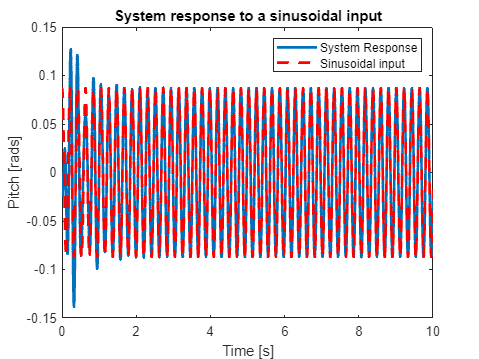

plot(x,yy,'--r','linewidth',2)
legend(["System Response","Sinusoidal input"])
hold off

M

M = 0.1455

spring_damping(1,:)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


% plot(0.1:1:68.1,spring_mat)

[minimum,index] =  min(spring_mat(1:69));
fprintf("The best spring constant for %d rad/s is %.2f N/rad", omega,index/10)

The best spring constant for 30 rad/s is 0.10 N/rad

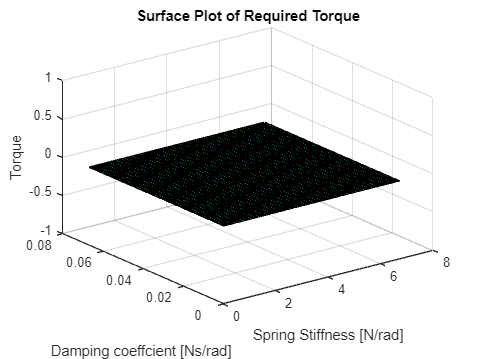

surf(spring_damping)
title('Surface Plot of Required Torque');
xlabel('Spring Stiffness [N/rad]');
ylabel('Damping coeffcient [Ns/rad] ');
zlabel('Torque');

% Scale the axes
xticks = get(gca, 'XTick');
yticks = get(gca, 'YTick');

set(gca, 'XTickLabel', xticks / 10);
set(gca, 'YTickLabel', yticks / 1000);